**Sensitivity analysis of delta (discount factor)**

  clear;clc;
  close all

% Enter model parameters
  alpha =  3.0;                  % growth function parameter
  beta  =  1.0;                  % growth function parameter
  gamma =  0.5;                  % demand function parameter
  cost  =  0.2;                  % marginal cost of harvest

% Construct state space
  n    = 200;                    % number of states
  smin = 0;                      % minimum state
  sbar = 8;                      % maximum state
  S    = nodeunif(n,smin,sbar);  % vector of states

% Construct action space
  m    = 100;                    % number of actions
  xmin = 0;                      % minimum action
  xmax = 6;                      % maximum action
  X    = nodeunif(m,xmin,xmax);  % vector of actions
  
% Sensitivity analysis of delta
  delta =  0.1:0.1:0.9;                  % discount factor
  
% Empty matrices to store values from change values of delta
  vs    = zeros(n, numel(delta));
  xs     = zeros(n, numel(delta));
  pstars = zeros(n, n, numel(delta));

% Construct reward function
  f = zeros(n,m);
  for k=1:m
     f(:,k) = (X(k).^(1-gamma))/(1-gamma)-cost*X(k);
     f(S<X(k),k) = -inf;
  end

% Construct state transition function
  g = zeros(n,m);
  for i=1:n
  for k=1:m
    snext  = alpha*(S(i)-X(k)) - 0.5*beta*(S(i)-X(k)).^2;
    g(i,k) = getindex(snext,S);
  end
  end

% Pack model structure
  for i=1:numel(delta)
  clear model
  model.reward     = f;
  model.transfunc  = g;
  model.discount   = delta(i);

% Solve infinite-horizon model using policy iteration
  [v,x,pstar] = ddpsolve(model);
  vs (:, i) = v;
  xs (:, i) = X(x);
  pstars (:,:,i) = pstar;
  end

Solve Bellman equation via Newton method
    1    4.4e+01
    2    5.7e-01
    3    4.5e-03
    4    0.0e+00
Solve Bellman equation via Newton method
    1    4.6e+01
    2    2.3e+00
    3    5.3e-02
    4    1.4e-03
    5    0.0e+00
Solve Bellman equation via Newton method
    1    4.8e+01
    2    5.0e+00
    3    2.3e-01
    4    1.3e-02
    5    1.9e-03
    6    0.0e+00
Solve Bellman equation via Newton method
    1    5.0e+01
    2    9.4e+00
    3    4.5e-01
    4    6.5e-02
    5    9.5e-03
    6    1.5e-03
    7    4.0e-04
    8    0.0e+00
Solve Bellman equation via Newton method
    1    5.3e+01
    2    1.6e+01
    3    9.7e-01
    4    1.2e-01
    5    1.5e-02
    6    3.0e-03
    7    0.0e+00
Solve Bellman equation via Newton method
    1    5.7e+01
    2    2.7e+01
    3    1.8e+00
    4    2.5e-01
    5    4.5e-02
    6    1.0e-02
    7    1.5e-03
    8    0.0e+00
Solve Bellman equation via Newton method
    1    6.3e+01
    2    4.6e+01
    3    4.0e+00
    4    2.9e-01

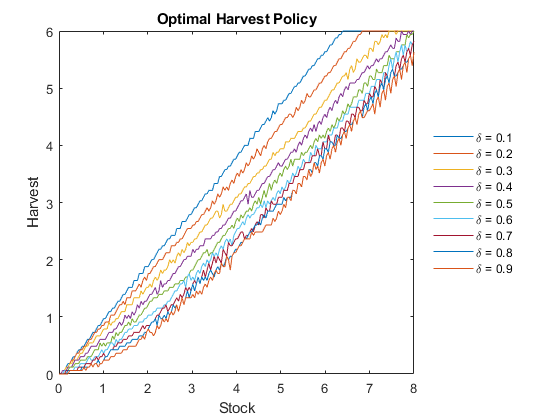

plot(S,xs);
title('Optimal Harvest Policy');
legend('Location',"eastoutside");
xlabel('Stock'); ylabel('Harvest');
legend("Box","off");
for i = 1:numel(delta)
    legendInfo{i} = ['\delta = ' num2str(i/10)]; 
end
legend(legendInfo)

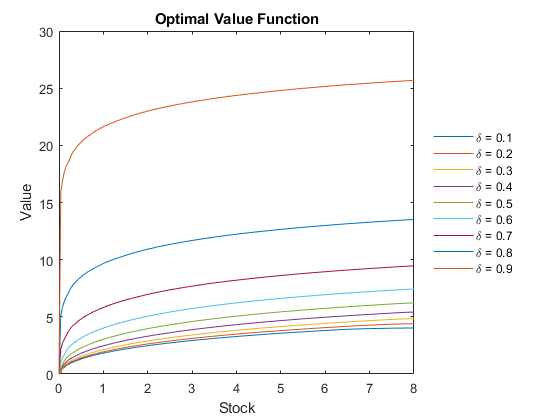

plot(S,vs); 
title('Optimal Value Function');
xlabel('Stock'); ylabel('Value');
lgd1 = legend('Location',"eastoutside");
legend("Box","off");
legend(legendInfo)

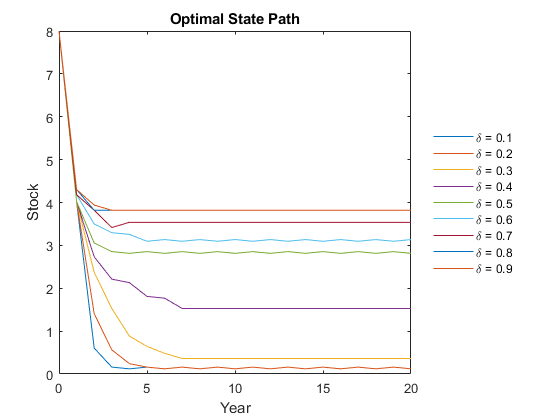

sinit =  max(S); 
nyrs = 20;
spaths = zeros(nyrs+1, numel(delta));
for z=1:numel(delta)
spath(:,:,z) = ddpsimul(pstars(:,:,z),n,nyrs);
spaths(:,z) = S(spath(:,:,z));
end

plot(0:nyrs,spaths)
title('Optimal State Path')
xlabel('Year'); ylabel('Stock');
lgd1 = legend('Location',"eastoutside");
legend("Box","off");
legend(legendInfo)

**Sensitivity analysis of alpha (growth factor)**

  clear;clc;
  close all

% Enter model parameters               
  beta  =  1.0;                  % growth function parameter
  delta = 0.9;                   % discount factor
  gamma =  0.5;                  % demand function parameter
  cost  =  0.2;                  % marginal cost of harvest

% Construct state space
  n    = 200;                    % number of states
  smin = 0;                      % minimum state
  sbar = 8;                      % maximum state
  S    = nodeunif(n,smin,sbar);  % vector of states

% Construct action space
  m    = 100;                    % number of actions
  xmin = 0;                      % minimum action
  xmax = 6;                      % maximum action
  X    = nodeunif(m,xmin,xmax);  % vector of actions
  
% Sensitivity analysis of delta
  alpha =  3:0.2:4;                  % growth function parameter
  
% Empty matrices to store values from change values of alpha
  vs    = zeros(n, numel(alpha));
  xs     = zeros(n, numel(alpha));
  pstars = zeros(n, n, numel(alpha));

% Construct reward function
  f = zeros(n,m);
  for k=1:m
     f(:,k) = (X(k).^(1-gamma))/(1-gamma)-cost*X(k);
     f(S<X(k),k) = -inf;
  end

  % Construct state transition function

% Pack model structure
  for l=1:numel(alpha)
  g = zeros(n,m);
  for i=1:n
  for k=1:m
    snext  = alpha(l)*(S(i)-X(k)) - 0.5*beta*(S(i)-X(k)).^2;
    g(i,k) = getindex(snext,S);
  end
  end
  clear model
  model.reward     = f;
  model.transfunc  = g;
  model.discount   = delta;

% Solve infinite-horizon model using policy iteration
  [v,x,pstar] = ddpsolve(model);
  vs (:, l) = v;
  xs (:, l) = X(x);
  pstars (:,:,l) = pstar;
  end

Solve Bellman equation via Newton method
    1    1.1e+02
    2    2.1e+02
    3    1.7e+01
    4    1.9e+00
    5    4.8e-01
    6    2.2e-01
    7    4.3e-02
    8    4.4e-03
    9    0.0e+00
Solve Bellman equation via Newton method
    1    1.1e+02
    2    2.4e+02
    3    2.5e+01
    4    2.3e+00
    5    5.8e-01
    6    1.7e-01
    7    5.5e-02
    8    1.2e-02
    9    0.0e+00
Solve Bellman equation via Newton method
    1    1.1e+02
    2    2.6e+02
    3    2.0e+01
    4    1.0e+00
    5    1.3e-01
    6    3.6e-02
    7    0.0e+00
Solve Bellman equation via Newton method
    1    1.2e+02
    2    2.7e+02
    3    3.0e+01
    4    1.3e+00
    5    1.3e-01
    6    5.2e-03
    7    0.0e+00
Solve Bellman equation via Newton method
    1    1.3e+02
    2    3.0e+02
    3    2.5e+01
    4    9.5e-01
    5    1.7e-01
    6    9.2e-02
    7    3.6e-02
    8    4.1e-03
    9    6.1e-04
   10    0.0e+00
Solve Bellman equation via Newton method
    1    1.3e+02
    2    3.2e+02
    3 

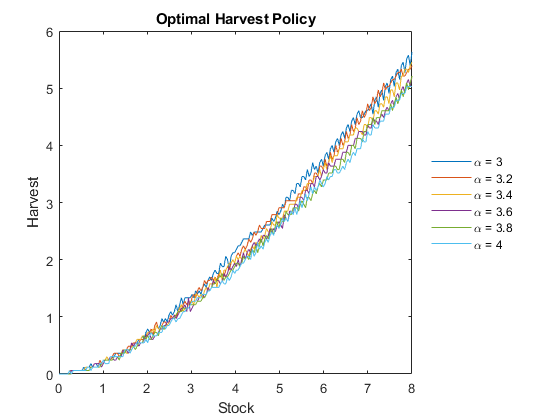

plot(S,xs);
title('Optimal Harvest Policy');
legend('Location',"eastoutside");
xlabel('Stock'); ylabel('Harvest');
legend("Box","off");
for i = 1:numel(alpha)
    legendInfo{i} = ['\alpha = ' num2str(3+(i-1)*0.2)]; 
end
legend(legendInfo)

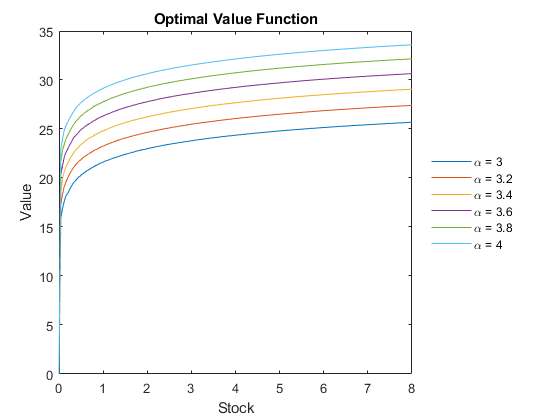

plot(S,vs); 
title('Optimal Value Function');
xlabel('Stock'); ylabel('Value');
lgd1 = legend('Location',"eastoutside");
legend("Box","off");
legend(legendInfo)

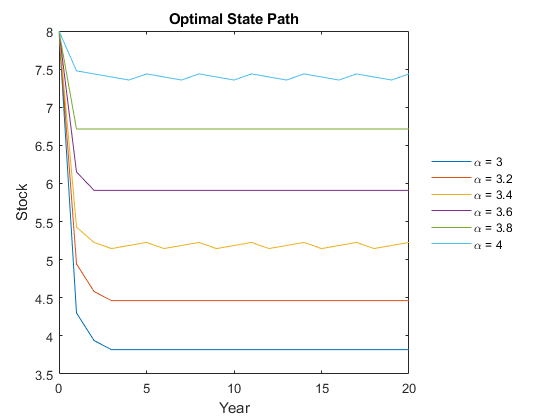

sinit =  max(S); 
nyrs = 20;
spaths = zeros(nyrs+1, numel(alpha));
for z=1:numel(alpha)
spath(:,:,z) = ddpsimul(pstars(:,:,z),n,nyrs);
spaths(:,z) = S(spath(:,:,z));
end

plot(0:nyrs,spaths)
title('Optimal State Path')
xlabel('Year'); ylabel('Stock');
lgd1 = legend('Location',"eastoutside");
legend("Box","off");
legend(legendInfo)